# MTRN4230 T2 2020

   %{
    THINGS TO DO
    1.  make a home configuration
    1.5 get simulation down pat + are we using grippers, vacuum what is the
    size of conveyor/positions everything necessary for #2-path planning
    2.  make path/trajectory planning algorithm
    3.  kinematics equations using home config and path plan, turn in into
    an algorithm?
    4.  find a way to return outputs of algorithms and make it apply to
    robot (i/o maybe?) need to discuss
   %}

## SETUP/CONNECT TO GAZEBO/ROS

clear all;
close all;
ipaddress = '192.168.0.59';
robotType = 'Gazebo';
rosshutdown;

Shutting down global node /matlab_global_node_25698 with NodeURI http://192.168.0.42:49507/


rosinit(ipaddress);

Initializing global node /matlab_global_node_15514 with NodeURI http://192.168.0.42:49750/


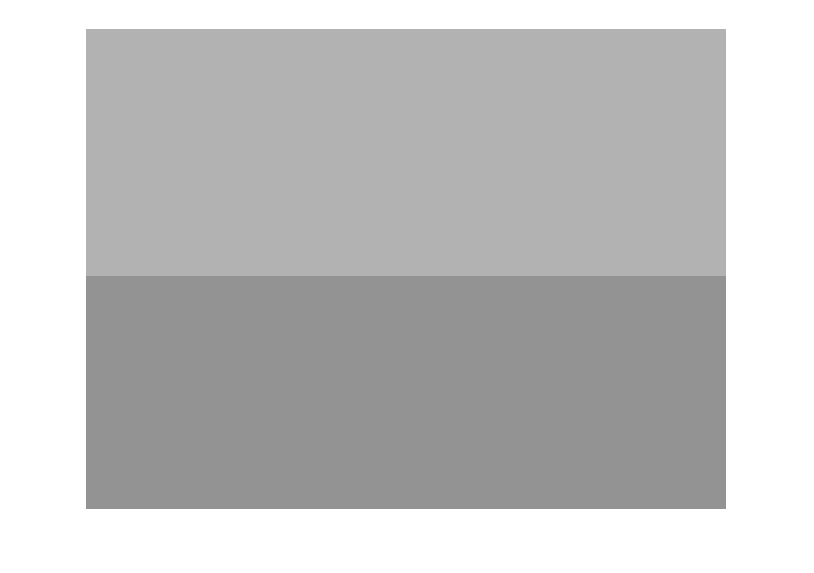

blockposes = rossubscriber('/gazebo/link_states');
pause(2);
posdata = receive(blockposes,10);
imSub = rossubscriber('/camera/color/image_raw');
pcSub = rossubscriber('/camera/depth/points');
testIm  = readImage(imSub.LatestMessage);
imshow(testIm);

rostopic list;

/arm_controller/command                                       
/arm_controller/follow_joint_trajectory/cancel                
/arm_controller/follow_joint_trajectory/feedback              
/arm_controller/follow_joint_trajectory/goal                  
/arm_controller/follow_joint_trajectory/result                
/arm_controller/follow_joint_trajectory/status                
/arm_controller/state                                         
/calibrated                                                   
/camera/color/camera_info                                     
/camera/color/image_raw                                       
/camera/color/image_raw/compressed                            
/camera/color/image_raw/compressed/parameter_descriptions     
/camera/color/image_raw/compressed/parameter_updates          
/camera/color/image_raw/compressedDepth                       
/camera/color/image_raw/compressedDepth/parameter_descriptions
/camera/color/image_raw/compressedDepth/parameter_updat

## load the robot

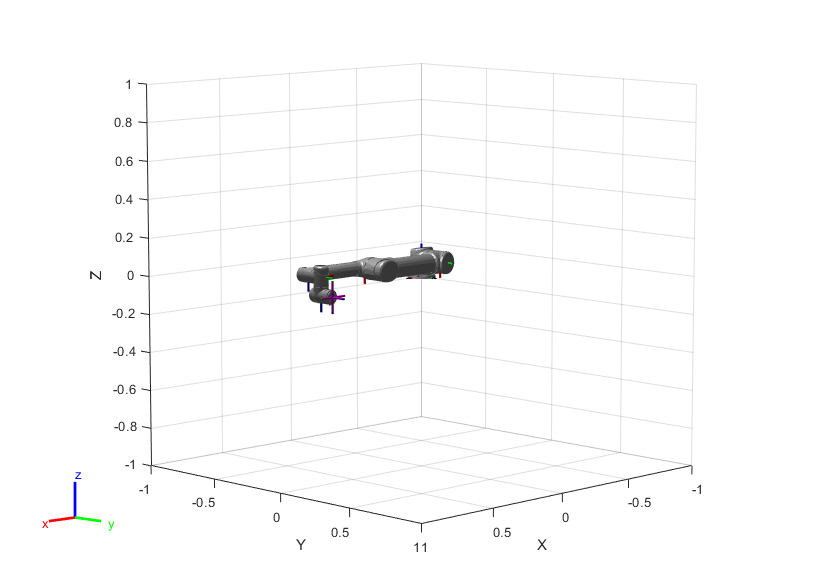

%In MATLAB, not Gazebo/ROS
robot = loadrobot("universalUR5");
%robot = rigidBodyTree; %load the UR5 into a rigidBodyTree
%for now use a random frame for the calcs since we don't have path planning
%yet- need a simulation for that
figure(1);
randPos = randomConfiguration(robot);
show(robot);

show(robot,randPos);
showdetails(robot);

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

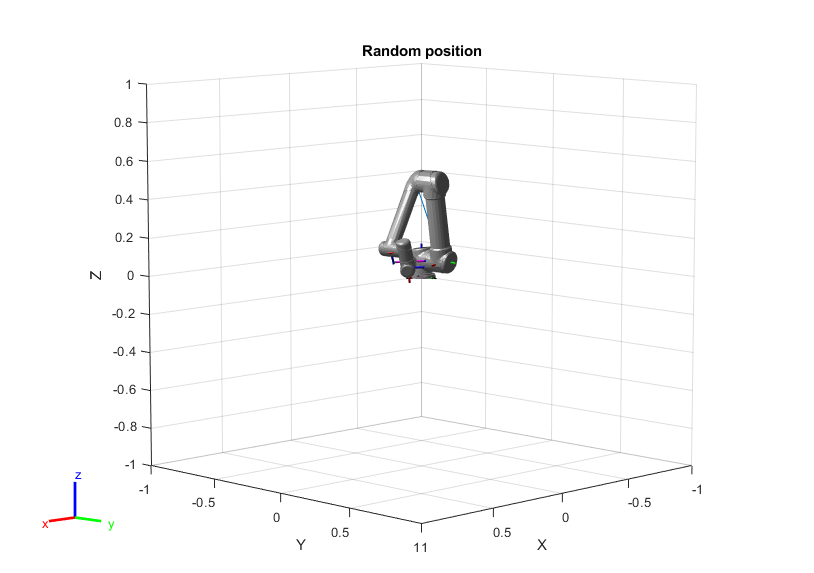

title('Random position');

## Joint States

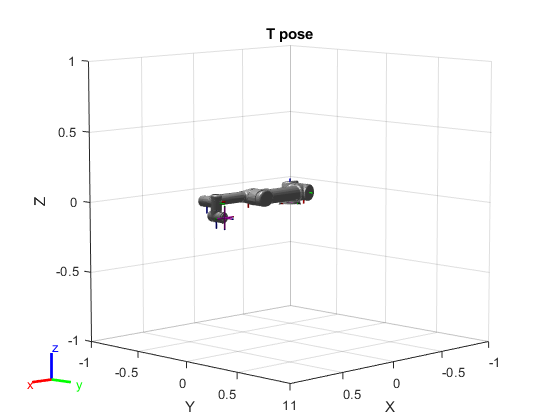

%Currently only records robot state at the instant the commands are called
%- need to put in a loop with the rest of the commands
jointSub = rossubscriber('joint_states'); 
jntState = receive(jointSub);
jntPos = exampleHelperJointMsgToStruct(robot,jntState);
figure(2);
show(robot);
title('T pose'); %Shows robot in default state a robot T pose if you will

%show(robot,jntState.Position); %Doesn't work since it expects a struct not
%a jointstate
show(robot,jntPos);
showdetails(robot);

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

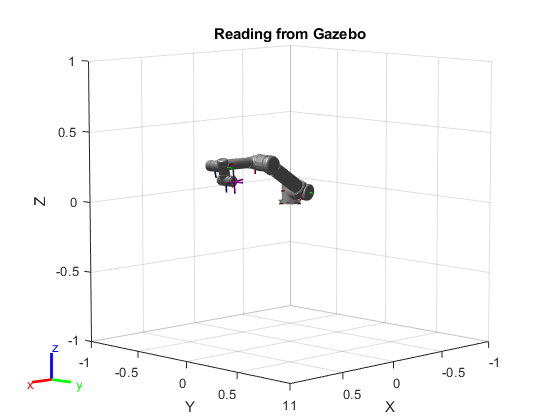

title('Reading from Gazebo')

%jntPos = exampleHelperJointMsgToStruct(ur5,jntState);
%Appears to copy the current motion  of the robot and displays in diagram

## kinematic equations

%getTransform does all the kinematics calcs for you but you need two
%coordinate frames. Right now it is the default(flat) robot frame and a
%randomly generated one. Need to replace the default frame with a
%homeConfiguration and the other frames will be decided based on path
%transform = getTransform(robot,randPos,'upper_arm_link','forearm_link');

%forward kinematics
transform = getTransform(robot,jntPos,'tool0','base')

transform =     0.9958   -0.0917   -0.0001   -0.7280
   -0.0001    0.0000   -1.0000   -0.1914
    0.0917    0.9958   -0.0000    0.2341
         0         0         0    1.0000



%inverse kinematics
ik = inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = jntPos;
[configSol,solInfo] = ik('tool0',transform,weights,initialguess)

configSol = 1×6 struct array with fields:
    JointName
    JointPosition


solInfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7717e-07
             ExitFlag: 1
               Status: 'success'


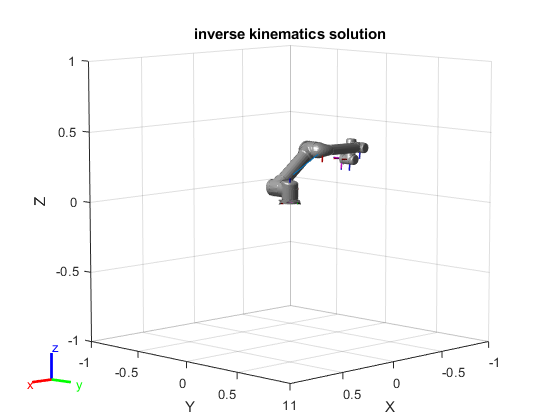

show(robot,configSol);
title('inverse kinematics solution');

## Path Planning

currPose = robot;

desPose = 

## Send commands to ROS/Gazebo to move arm